## Final exam  21-06-2023

### Problem 2

Consider the Poisson heat difussion on the square of side length $\ell = 3$ shown below, meshed by four rectangular triangular finite elements

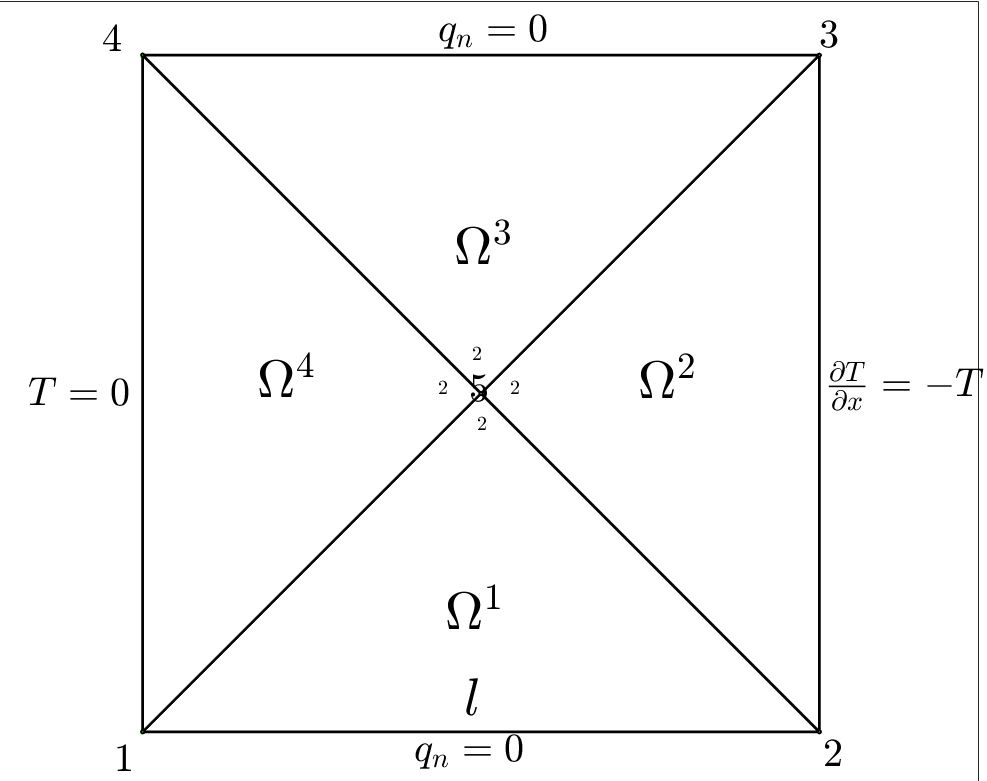

with the local and global numbering plotted there. We consider that the thermal conductivity is $k_{c} = 1$ and the internal heating is $f = 2$. Also suppose that the temperature is $T = 0$ on the side determined by the nodes 1 and 4; $q_{n}$ = 0 , on the sides between nodes$1$and 2, and $3$and $4$; and on the edge between nodes $2$ and $3$, the BC is $\frac{\partial T}{\partial x} = -T}$. ( you can also formulate this BC as a convection problem for suitables $\beta $ and $T_{\infty}$ ). Answer the following questions :

(a) (3 points)  The value of $F_{5}$ of the global vector forces is:

*Hint* $1$. The value of the entry $K_{54}$ of the global stiffness matrix $K$ is -1.0000e+00.

**Solution.**

First we compute the local stiffness matrices and the local force vectors for each element. On the one hand, as we consider the Poisson equation equation ($a_{11} = a_{22} = c$, $a_{12} = a_{21} = a_{00} = 0$), and all the $4$ elements are (linear) *right triangles, *to find the stiffness matrices we can use the specific formula:


$$K^{e} = \frac{c}{2 a b}\left(
\begin{array}{ccc}
~~~b^{2} & -b^ {2} & 0\\
-b^{2} & a^{2} + b^{2} & -a^{2}\\
~~0 & -a^{2} & ~~a^ {2}
\end{array}
\right).$$


Recall that, for the above formula to hold, local node 2 must be placed at the right angle of the triangle $\Omega^{e}$; then, $a$ is the length of the triangle's edge joining local nodes$1$ and $2$, and $b$ is the lenght of the triangle's edges joining local nodes $2$ and $3$. In our problem at hand $c = k_{c} = 1/2$, and $a = b$ for all the triangles. Hence,

$K^{e} = \frac{1}{2}\left(
\begin{array}{rrr}
1 & -1 & 0\\
-1 & 2 & -1\\
0 & -1 & 1
\end{array}
\right),$ for $e=1,2,3,4$,

and the local stiffness matrices are the same for all the four triangles. On the other hand, as the r.h.s. of the equation, the internal heating, is also constant for each element, we can use the formula,


$$F^{e} = \frac{f^{e} A^{e}}{3}\left(\begin{array}{c} 
1 \\
1\\
1
\end{array}
\right).$$


Here $f^{e} = f = 2$, and the area $A^{e} = \ell^{2}/4 = 9/4$ are the same for all the triangles, $e=1,2,3,4$. Thus, in this case in point,

$F^{e} = \frac{3}{2}\left(\begin{array}{c} 
1 \\
1\\
1
\end{array}
\right),$ for $e=1,2,3,4$,

and the local force vectors are the same for all the four triangles. Therefore,


$$F_{3} = F_{2}^{1} + F_{2}^{2} + F_{2}^{3} + F_{2}^{4} = 4\times\frac{3}{2} = 6, \text{ and } K_{54} = K_{23}^{4} + K_{21}^{3} = \frac{1}{2}\left(-1 - 1\right) = -1.$$


(b) (3 points) One knows that $Q_{2} = c_{2} T_{2} + c_{3} T_{3}$ for some $c_{2}$ and $c_{3}$. Then, the value of $c_{2}$ is

*Hint *$2$. this coefficient for $Q_{2} + Q_{3}$ is -1.5000e+00.

**Solution.**

First, we note that the BC $\frac{\partial T}{\partial x} = - T$ on the vertical right edge can be thought of as a convenction BC with $\beta = k_{c}$ and $T_{\infty} = 0$, so $q_{n} = -k_{c}T$ along the vertical right edge. Then, using the formulas for the linear flows:


$$\begin{array}{rcl}
Q_{2} 
\!\!\! &=& \!\!\! 
Q_{13}^{1} + Q_{33}^{2} =
Q_{33}^{2} =
-\beta \ell\left(\frac{T_{2}}{3} + \frac{T_{3}}{6}\right) =  -k_{c} \ell\left(\frac{T_{2}}{3} + \frac{T_{3}}{6}\right) = -3\left(\frac{T_{2}}{3} + \frac{T_{3}}{6}\right)\\
\!\!\!\!\! &=& \!\!\!\!\! 
 -T_{2} - \frac{T_{3}}{2},\\
%%%
Q_{3} 
\!\!\! &=& \!\!\! 
Q_{33}^{3} + Q_{13}^{2} = 
Q_{13}^{2} =
 -\beta\ell\left(\frac{T_{2}}{6} + \frac{T_{3}}{3}\right) =  -k_{c}\ell\left(\frac{T_{2}}{6} + \frac{T_{3}}{3}\right) = -3\left(\frac{T_{2}}{6} + \frac{T_{3}}{3}\right)\\
\!\!\!\!\! &=& \!\!\!\!\! 
 -\frac{T_{2}}{2} - T_{3}
\end{array}$$


(we stress that $Q_{13}^{1}=0$ and $Q_{33}^{3} = 0$, since $q_{n}\equiv 0$ in the horizontal lower and upper edges respectively). Now, 

- If we write $Q_{2} = c_{2}T_{2} + c_{3} T_{3}$, comparison of coeffcients leads to $c_{2} = -1$.

- $Q_{2} + Q_{3} = -\frac{3}{2} T_{2} - \frac{3}{2} T_{3}$ so, if we write $Q_{2} + Q_{3} = c_{2} T_{2} + c_{3} T_{3}$, comparison of coefficients leads to $c_{2} = -\frac{3}{2} = -1.5$. 

(c) (4 points)  The temperature of node $5$, $T_{5}$, is :

*Hint *$3$. $T_{2} - T_{3}$ is $0$.

**Solution.** 

Since, from the (essential) BC we have, $T_{1} = T_{4} = 0$, the equations for the* free nodes*, nodes  $2$, 3, and $5$,are:


$$\begin{array}{rcl}
K_{22}T_{2} + K_{23}T_{3} + K_{25}T_{5} 
\!\!\!\! & = &  \!\!\!\!
 \left(K_{11}^{1} + K_{33}^{2}\right)T_{2} + K_{31}^{2} T_{3} + \left(K_{12}^{1} + K_{32}^{2}\right) T_{5}\\
\!\!\!\!  & = &  \!\!\!\! 
\frac{1}{2}\left(1 + 1\right) T_{2} + 0\cdot T_{3} + 
\frac{1}{2}\left(-1-1\right) T_{5}\\
\!\!\!\! & = &  \!\!\!\!
T_{2}  - T_{5} =
Q_{2} + F_{2},\\
%%%
K_{32} T_{2} + K_{33} T_{3} + K_{35} T_{5} 
\!\!\!\! & = &  \!\!\!\!
K_{23} T_{2} + \left(K_{11}^{2} + K_{33}^{3}\right) T_{3} +
\left(K_{32}^{3} + K_{12}^{2}\right) T_{5}\\
\!\!\!\! & = &  \!\!\!\!
0\cdot T_{2} + \frac{1}{2}\left(1 + 1\right) T_{3} + 
\frac{1}{2}\left(-1-1\right) T_{5}\\
\!\!\!\! & = &  \!\!\!\!
T_{3} - T_{5} = 
 F_{3} + Q_{3},\\
%%%
K_{52}T_{2} + K_{53}T_{3} + K_{55} T_{5} 
\!\!\!\! & = &  \!\!\!\!
K_{25}T_{2} + K_{35}T_{3} + \left(K_{22}^{1} + K_{22}^{2} + K_{22}^{3} + K_{22}^{4}\right) T_{5}\\
\!\!\!\! & = &  \!\!\!\!
\frac{1}{2}\left(-1 -1\right)T_{2} +
\frac{1}{2}\left(-1-1|\right) T_{3} 
+ \frac{1}{2}\left(2 + 2 + 2 + 2\right)T_{5}\\
\!\!\!\! & = &  \!\!\!\!
-T_{2} -T_{3} + 4T_{5} = Q_{5} + F_{5}.
\end{array}$$


*Remark*: we note that, as $T_{1}$ and $T_{4}$ are both $0$, then $K_{i1} T_{1} + K_{i4} T_{4} = 0$, for $i=2,3, 5$, and no term has to be moved to the rhs in the above equations. 

With,


$$\begin{array}{l}
F_{2} = F_{1}^{1} + F_{3}^{2} = \frac{3}{2} + \frac{3}{2} = 3,\\
F_{3} = F_{1}^{2} + F_{3}^{3} = \frac{3}{2} + \frac{3}{2} = 3,\\
F_{5} = F_{2}^{1} + F_{2}^{2} + F_{2}^{3} + F_{2}^{4} = 
 \frac{3}{2} + \frac{3}{2} +  \frac{3}{2} + \frac{3}{2} = 6.
\end{array}$$


and $Q_{2}, Q_{3}, Q_{5}$ given by the (natural) BC, i.e.,  

 $Q_{2} = -T_{2} - \frac{T_{3}}{2},\qquad Q_{3} = -\frac{T_{2}}{2} - T_{3},\qquad Q_{5} = 0$,

Hence, after substitution of these quantities in the above equations, we get,


$$\begin{array}{rcl}
T_{2} - T_{5}\!\!\!\!\! &=&\!\!\!\!\! 
         -T_{2} - \frac{T_{3}}{2} +3,\\
T_{3} - T_{5}\!\!\!\!\!  &=&\!\!\!\!\! -\frac{T_{2}}{2} - T_{3} + 3,\\
-T_{2} - T_{3} + 4T_{5}\!\!\!\!\! &=&\!\!\!\!\! 6,
\end{array}$$


Now moving to the lhs the terms with $T_{2}$ and $T_{3}$ that appear at the rhs of the first two equations, we see that the reduced system writes as


$$\begin{array}{l}
2T_{2} + \frac{1}{2}T_{3} - T_{5} = 3,\\
\frac{1}{2} T_{2} + 2T_{3} - T_{5} = 3,\\
-T_{2} - T_{3} + 4T_{5} = 6.
\end{array}$$


Substracting the second equations to the first in this last system, it is readily seen that $T_{2}  = T_{3}$. Then we can reduce it to the following two linear equation system in $T_{2}$ and $T_{5}$,


$$\begin{array}{rcl}
5T_{2} - 2T_{5}\!\!\!\!\! &=&\!\!\!\!\! 6,\\
-2T_{2} + 4T_{5}\!\!\!\!\! &=&\!\!\!\!\! 6, 
\end{array}$$


that can be solved straightforward, for example by Cramer's rule:


$$T_{2} =
\frac{\left|\begin{array}{rr}
6 & -2\\
6 & 4
\end{array}
\right|}%
{\left|\begin{array}{rr}
5 & -2\\
-2 & 4
\end{array}
\right|} = \frac{9}{4}, 
\qquad

T_{5} =
\frac{\left|\begin{array}{rr}
5 & 6\\
-2 & 6
\end{array}
\right|}%
{\left|\begin{array}{rr}
5 & -2\\
-2 & 4
\end{array}
\right|}  = \frac{21}{8}.$$


So finally, the temperatures at the nodes are:


$$T_{1} = 0, \qquad T_{2} = T_{3} = \frac{9}{4}, \qquad T_{4} = 0, 
\qquad T_{5} = \frac{21}{8}.$$


Let us check this result with Matlab...

T = zeros(5,1);
freeNodes = [2,3,5];
format rat; % We know that the solutions of the system is
            % rational,so show the numbers as rationals 

% Reduced system                            
Km = [2, 1/2,-1; 1/2, 2, -1; -1, -1, 4]; Fm = [3; 3; 6];

% Solve the reduced system 
Tm = Km\Fm;
T(freeNodes) = Tm;

% Set up a table showing temperature at each node 
sz = [5, 2];
varTypes = ["int64", "double"];
varNames = ["node", "T(ºC)"];
sols = table('Size', sz,...
    'VariableTypes', varTypes,...
    'VariableNames', varNames);
sols(:,1) = table((1:5)'); sols(:,2) = table(T); 
sols

sols = 5×2 table
    node    T(ºC)
    ____    _____

     1          0
     2       2.25
     3       2.25
     4          0
     5      2.625


format short e; format compact % back to floating point 